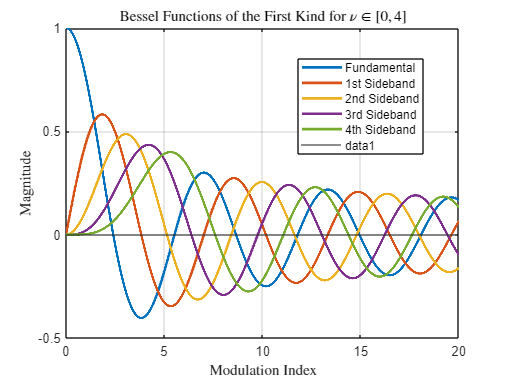

clear

z = 0:0.001:20;
J = zeros(5,numel(z));
for i = 0:4
    J(i+1,:) = besselj(i,z);
end


plot(z,J, "lineWidth", 2)
grid on
legend('Fundamental','1st Sideband','2nd Sideband','3rd Sideband','4th Sideband','Location','Best')
title('Bessel Functions of the First Kind for $\nu \in [0, 4]$','interpreter','latex')
xlabel('Modulation Index','interpreter','latex')
ylabel('Magnitude','interpreter','latex')
% ylabel('$J_\nu(z)$','interpreter','latex')
hold on;
yline(0)